# Module 2 Project 2 Owen Rogg

%{
Made by Owen Rogg on April 6th 2026
Module 2 Project 2, from bank 2 project #16
Drone Battery And Flight Time
Objective is to estimate flight duration based on power consumption.

Core Tasks:
Model battery energy depletion over time
Define power consumption for different flight modes (hover, cruise, ascent)
Determine total achievable flight time before battery depletion. 

I am going to start by asking the user for battery voltage and amperage. I
will create 3 different functions, each representing a flight mode and each
will have a different impact on power consumption. I'll create a time value
that goes from 1-30 minutes, and then each flight mode will consume a
certain amount of watts per minute. Wattage in the users battery will be
determined by the voltage and amperage input. I will create 3 plots of
power vs time, each one corresponding to a flight mode.
%}
%Clearing any previous input just to get started.
clear
clc
close all
%ask for volts and amps, convert to useable number format
voltstr = inputdlg('What is the voltage of your battery?');
volt=str2num(voltstr{1});
ampstr = inputdlg('What is the amperage of your battery?');
amp = str2num(ampstr{1});
watt = volt * amp; % Calculate total wattage
t = 1:30; % Time in minutes
%Set up each flight mode
hover= watt -3*t;
%Ensure that the power consumption cannot go below 0
hover(hover < 0) = NaN ;

% Find the time(s) when hover reaches zero (or would reach zero)
% Solve watt - 3*t == 0 -> t = watt/3
t_hovzero = watt/3;
% Find the integer minute index within the defined time vector t
if any(abs(t - t_hovzero) < eps)
    t_at_zero = t_hovzero;
else
    % If exact match not in vector, report the fractional time and nearest minute
    t_at_zero = t_hovzero;
    nearest_minute = t(round(min(max(1,round(t_hovzero)),numel(t))));
end
% Display result to user
if t_at_zero >= min(t) && t_at_zero <= max(t)
    fprintf('Hover reaches 0 watts at t = %.2f minutes.\n', t_at_zero);
else
    fprintf('Hover would reach 0 watts at t = %.2f minutes, which is outside the 1-30 min range.\n', t_at_zero);

end

Hover reaches 0 watts at t = 18.67 minutes.


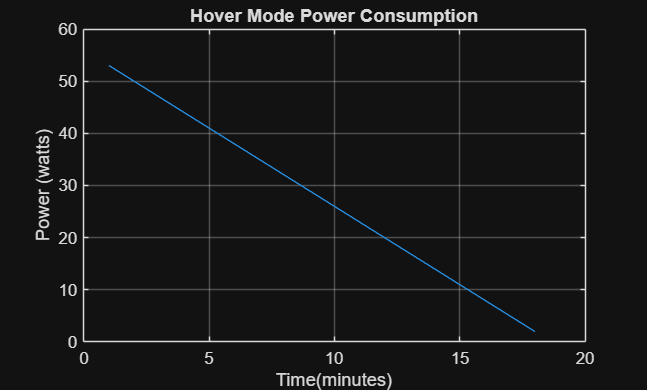

%Plot the hover graph
plot (t,hover)
xlabel('Time(minutes)')
ylabel('Power (watts)')
title('Hover Mode Power Consumption')
grid on 

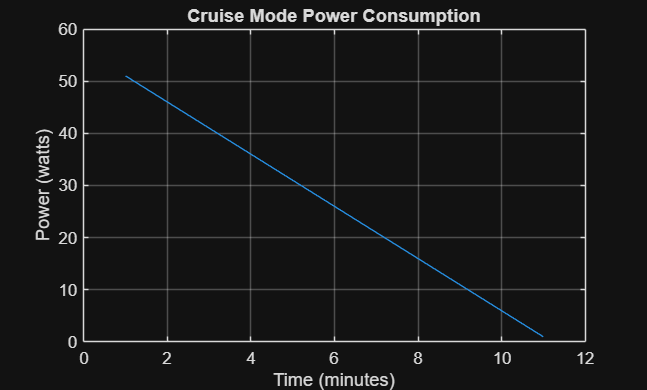

%Create cruise mode 
cruise = watt - 5*t; 
% Ensure that the power consumption cannot go below 0
cruise(cruise < 0) = NaN;
% Plot the cruise graph
figure; % Create a new figure for the cruise mode
plot(t, cruise)
xlabel('Time (minutes)')
ylabel('Power (watts)')
title('Cruise Mode Power Consumption')
grid on 

% Find time when cruise reaches 0: solve watt - 5*t == 0 -> t = watt/5
t_cruzzero = watt / 5;

% Check if the zero time lies within the defined time vector range
if t_cruzzero >= min(t) && t_cruzzero <= max(t)
    fprintf('Cruise reaches 0 watts at t = %.2f minutes.\n', t_cruzzero);
else
    fprintf('Cruise would reach 0 watts at t = %.2f minutes, which is outside the 1-30 min range.\n', t_cruzzero);
end

Cruise reaches 0 watts at t = 11.20 minutes.


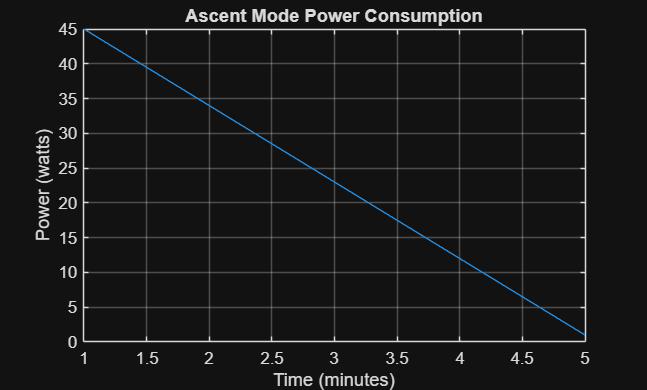


% Create ascent mode
ascent = watt - 11*t; 
% Ensure that the power consumption cannot go below 0
ascent(ascent < 0) = NaN;
% Plot the ascent graph
figure; % Create a new figure for the ascent mode
plot(t, ascent)
xlabel('Time (minutes)')
ylabel('Power (watts)')
title('Ascent Mode Power Consumption')
grid on 

% Find time when ascent reaches 0: solve watt - 11*t == 0 -> t = watt/11
t_aszzero = watt / 11;
% Check if the zero time for ascent lies within the defined time vector range
if t_aszzero >= min(t) && t_aszzero <= max(t)
    fprintf('Ascent reaches 0 watts at t = %.2f minutes.\n', t_aszzero);
else
    fprintf('Ascent would reach 0 watts at t = %.2f minutes, which is outside the 1-30 min range.\n', t_aszzero);
end

Ascent reaches 0 watts at t = 5.09 minutes.


%Note that these values ARE arbitrary and do not reflect an actual flight
%pattern for any drone. Values would change depending on weight
%and aerodynamics of each drone, and voltage would drop as power is spent,
%which cannot be accounted for here as that depends on each individual
%battery data sheet.